# [IPSA] - Automatique - Projet drone

# Document principal

Auteur : Adrien Jacob 

Le document ***Au425_projet_drone_introduction.pdf*** donne les directives principales de ce projet de fin d'année.

**/!\ ----- Informations concernant Simulink ----- /!\ **

______________________________________________________________________________________________________________________________________

- Les simulations sur Simulink se réaliseront en **"fixed step"** afin de se rapprocher des conditions réelles d'un micro-controleur.

            Ainsi, **TOUS les Simulinks **seront configurés de la manière suivante :  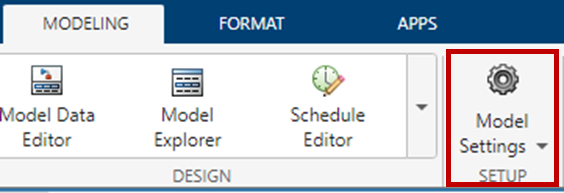

            **puis :**             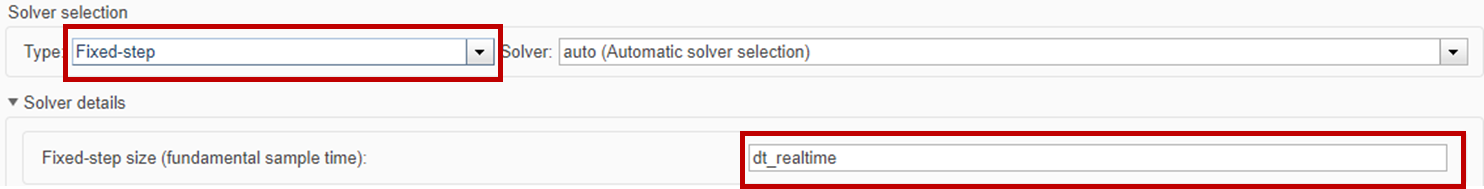

- **Toolbox Unreal Engine**

**            => En copiant le bloc depuis la librairie template, vous devrez changer le nom du drone et le sélectionner dans le bloc "Simulation 3D Scene Configuration"**

            **=> **Si vous ne souhaitez pas lancer la simulation Unreal Engine à chaque fois (phase de conception), modifiez le booléen `bool.Unreal_Engine = false`

______________________________________________________________________________________________________________________________________            

clc; clear; close all;
addpath Images\ Simulink\ Parametres_modelisations\

% à ajuster en fonction de la puissance de votre ordi pour le temps réel
% 1/60 : puissant  **  1/40 : normal 
dt_realtime = 1/40;

% Unreal Engine :
bool.Unreal_Engine = true; % active/desactive le bloc Unreal Engine avec un triger booléen

**______________________________________________________________________________________**

## 1. Définition du système en représentation d'état linéaire

% Récupération des données liées au drone
run drone_parameters_default.mlx

=== Paramètres du drone ===
 
                 g: 9.8100
                 m: 1.3800
                 L: 0.1750
                 h: 0.0167
          z_ground: 0.1500
      Moteur_T_max: 34
    Moteur_T_hover: 3.3844
    Moteur_T_dispo: 5.1156
    Moteur_RPM_max: 10500
    Moteur_RPM_min: 0
         angle_max: 0.3491
             v_ref: [20 20 5 3.1416]
                kt: 7.0304e-06
                kc: 1.4061e-06
                km: 0.2000
       Wmot2_hover: 4.8140e+05
         Wmot2_sat: [0 1.2090e+06]
                 M: [4×4 double]
                 I: [3×3 double]
                Ix: 0.0221
                Iy: 0.0221
                Iz: 0.0423
               kvx: 0.1000
               kvy: 0.1000
               kvz: 0.3000
                kp: 0.0100
                kq: 0.0100
                kr: 0.0050



B_mot =          0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
    0.7246    0.7246    0.7246    0.7246
         0         0         0         0
   -7.9223    7.9223    7.9223   -7.9223
         0         0         0         0
   -7.9223   -7.9223    7.9223    7.9223
         0         0         0         0
   -4.7323    4.7323   -4.7323    4.7323


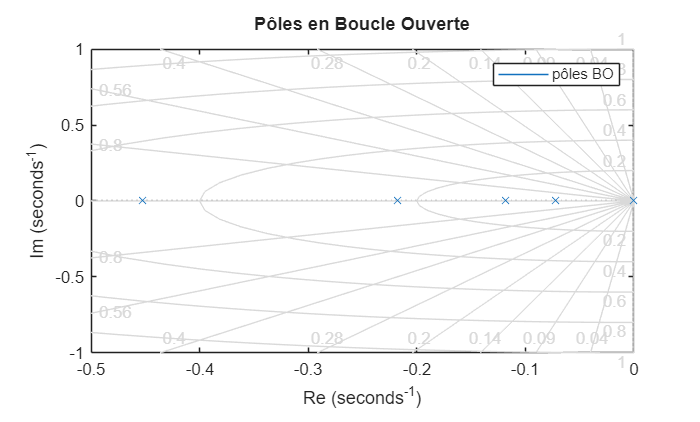

 
                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  0.00e+00    -1.00e+00       0.00e+00              Inf    
  0.00e+00    -1.00e+00       0.00e+00              Inf    
 -7.25e-02     1.00e+00       7.25e-02         1.38e+01    
 -7.25e-02     1.00e+00       7.25e-02         1.38e+01    
 -1.18e-01     1.00e+00       1.18e-01         8.45e+00    
 -2.17e-01     1.00e+00       2.17e-01         4.60e+00    
 -4.53e-01     1.00e+00       4.53e-01         2.21e+00    
 -4.53e-01     1.00e+00       4.53e-01         2.21e+00    


% Création du modèle d'état linéarisé
run drone_modelisation.mlx 

%sysBO_default = ss(A,B,C,D);
sysBO_default = sysBO;

_____________________________________________________________________________________

Le système `sys_BO` est-il contrôlable ? Démontrez le.

Un modèle est commendable/controlable si l'entrée u est capable d'emmener le système dans n'importe quel état x dans un temps fini. Soit : Un système d'ordre n est commandable si et seulement si sa matrice de commandabilité est de rang plein rank{C} = n. La matrice est définie par :

{C} = [B  AB A^2B ... A^{n-1}B]

n = length(sysBO_default.A); % Ordre du système
C0=[sysBO_default.B];
for i = 1: n-1
    C0 = [C0 sysBO_default.A^(i)*sysBO_default.B ];
end

if rank(C0) == n
    fprintf('La matrice C0 est commandable\n');
else
    fprintf("Le rang de C0 n'est pas égal à l'ordre du système, il n'est donc pas commandable\n");

end

La matrice C0 est commandable




Co = ctrb(A,B); rank_Co = rank(Co);
Ob = obsv(A,C); rank_Ob = rank(Ob);
disp(rank_Ob)

    12



disp(rank_Co)

    12



**______________________________________________________________________________________**

## **2. Simulation en boucle ouverte (Simulink)**

### **2.1. Boucle ouverte avec une commande en échelon**

**Nom du Simulink demandé :** Simulink_drone_BO

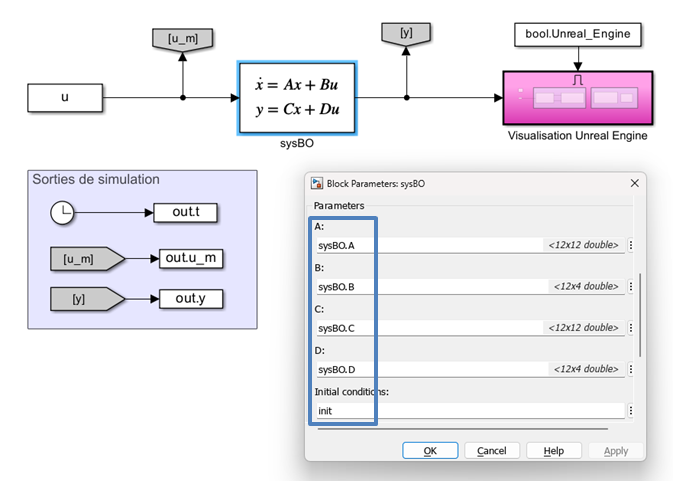

**P.S.** On a construit `sysBO` avec `ss(A, ``B_mot``, C, D)`, ainsi `sysBO.B` pointe bien vers `B_mot` !

_____________________________________________________________________________________

Construisez la simulation en Boucle ouverte suivante : 

- Un état initial $x_{\textrm{init}}$ défini par le groupe comme point de départ stable sur la map Unreal Engine : [Documentation Map](https://fr.mathworks.com/help/vdynblks/ref/uscityblock.html)

- Une contrainte de vitesse de lacet $r_0$ non nulle à l'état initial.

- Une entrée $u_M$ nulle : $u_{\textrm{M0}} ={\left\lbrack \begin{array}{cccc}
{\omega_1 }^2 =0 & {\omega_2 }^2 =0 & {\omega_3 }^2 =0 & {\omega_4 }^2 =0
\end{array}\right\rbrack }^T$

- Le rendu sera pour l'instant demandé uniquement dans l'environnement Unreal Engine.

- On cherchera à trouver des conditions initiales permettant de présenter une simulation effectuant approximativement un tour complet avant arret du drone et de la simulation.

*Inspiration => TD 02*

**Etat initial et ****commande**** de réference**

StopTime = 10;
t = 0 : dt_realtime : StopTime;

% création de la commande u (timeseries)
u=[0 0 0 0];
ones(length(t),4);
u = timeseries(u .* ones(length(t),1) , t);

% Etat initial du système à t = 0
x_init=[0 ; 0 ; 0 ; 0 ; 0 ; 0 ; 0 ;0;0;0;0;0];



**Simulation :**

% Simulation
sim1_BO=sim("Simulink_drone_BO.slx")

sim1_BO =   Simulink.SimulationOutput:

                      t: [1x1 timeseries] 
                   tout: [401x1 double] 
                    u_m: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


### **2.2. Boucle ouverte avec une commande temps réel à la manette (facultatif)**

(nécessite une manette reconnue par votre système d'exploitation)

***Cette partie est ******facultative******.**** Si vous voulez gagner du temps, passez cette partie.*

*L'objectif est de comprendre la difficulté de stabiliser en boucle ouverte un système comme celui-là.*

- Implémentez le bloc Simulink Template : "commande manuelle" **à la place de l'entrée **$u$ **dans un autre Simulink (nom au choix)**

- La commande "manette" sera construit sur la commande virtuelle $u_v ={\left\lbrack \begin{array}{cccc}
T & C_{\varphi }  & C_{\theta }  & C_{\psi } 
\end{array}\right\rbrack }^T$

- Pour l'adapter à la commande moteur, il est nécéssaire d'inclure la matrice $M^{-1}$ : $u_M =M^{-1} \ldotp u$ `(cf. drone_modelisation.mlx)`

- Definissez en "dur" un Stoptime élevé (ex 60s)

- Lancez depuis Simulink.

- Le switch de manette (ps5/x-box) s'effectue dirrectement en cliquant dans le Simulink

        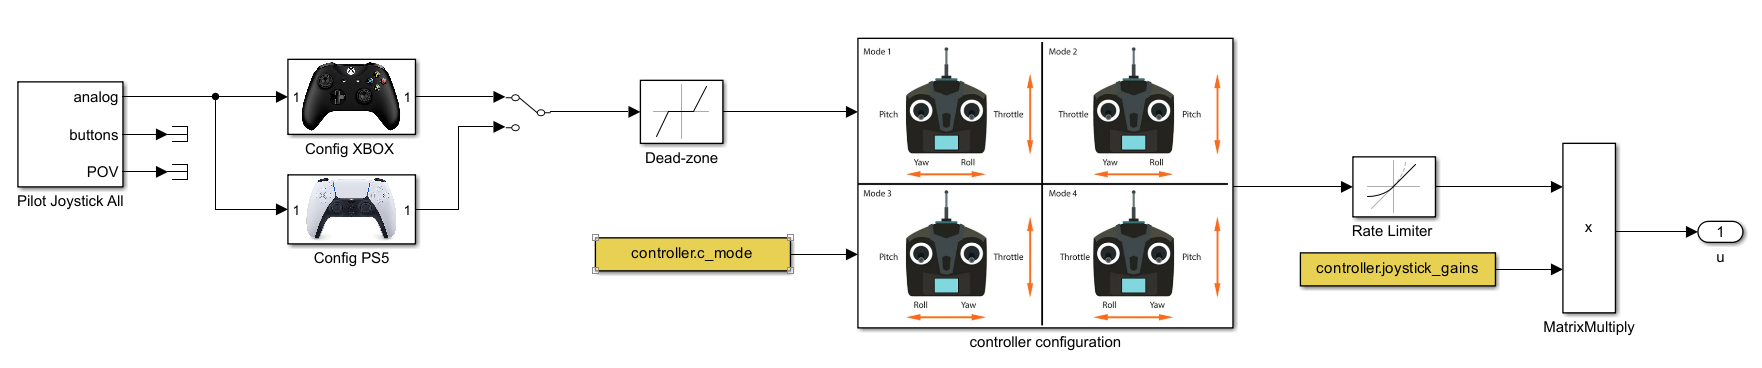        

    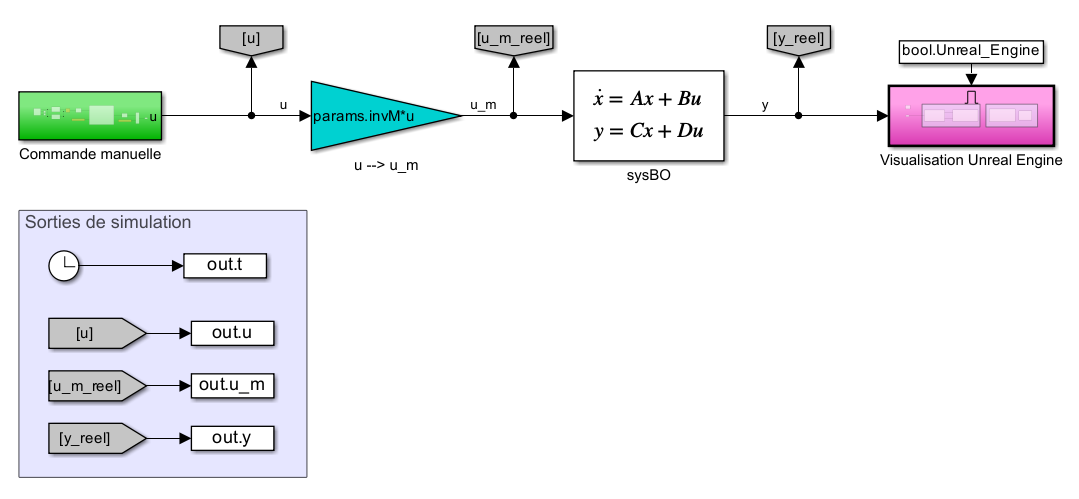

**       P.S. **le params.invM ***u** est ici un tag visuel qui indique l'option **multiplication matricielle** dans le bloc de gain.

run controller_parameters.mlx;

- Definissez en dur un Stoptime élevé (ex 60s)

- Lancez depuis Simulink.

- Si vous obtenez une erreur Joystick, changez de canal dans le premier bloc.

**______________________________________________________________________________________**

## **3. Choix des pôles / cahier des charges**

### **3.1. Pôles par défaut non optimisés**

On a trouvé ce jeu de placement de pôle pour un autre drone, non optimisé pour notre drone et ses capacités.

% configuration par défaut :

p_x =       [-0.5+0.3i, -0.5-0.3i];     % dynamique longitudinale (x, dx)
p_y =       [-0.5+0.3i, -0.5-0.3i];     % dynamique latérale (y, dy)
p_z =       [-0.5, -0.6];               % dynamique verticale (z, dz)

p_phi =     [-3, -3.2];                 % dynamique de roulis (phi, p)
p_theta =   [-3, -3.2];                 % dynamique de tangage (theta, q)
p_psi =     [-2, -2.2];                 % dynamique de lacet (psi, r)

p_default = [p_x p_y p_z p_phi p_theta p_psi];
clear p_x p_y p_z p_phi p_theta p_psi;

**______________________________________________________________________________________**

## **4. Procedure de placement de pôles et ajustement statique de la consigne**

- Réalisez la procédure de placement de pôle en calculant la matrice de gain $K$, puis la matrice d'ajustement statique $N$

- Fermez ensuite la boucle du système avec ce retour d'état.

Selectionnez les sorties de références à asservir $C_s$ :

C_x=sysBO.C([1, 3, 5, 11], :);


Réalisez la procédure de placement de pôle en calculant la marice de gain $K$ :

**P.S. **En fonction de `B_mot` (ou de `sysBO.B)` pour appliquer une commande adaptée aux entrées réelles

K=place(sysBO_default.A,sysBO_default.B,p_default);

Calculer la matrice d'ajustement statique $N$:

**P.S.** même chose

N=-pinv(C_x*(inv(sysBO_default.A-(sysBO_default.B)*K)*sysBO_default.B));

Construisez le système en boucle fermé avec la commande moteur $u_M$ :

**P.S.** même chose

u_m = ss( sysBO_default.A-(sysBO_default.B*K) , sysBO_default.B*N ,sysBO_default.C,sysBO_default.D);


**______________________________________________________________________________________**

## **5. Simulation en boucle fermée**

**Nom du Simulink demandé :** Simulink_drone_BF

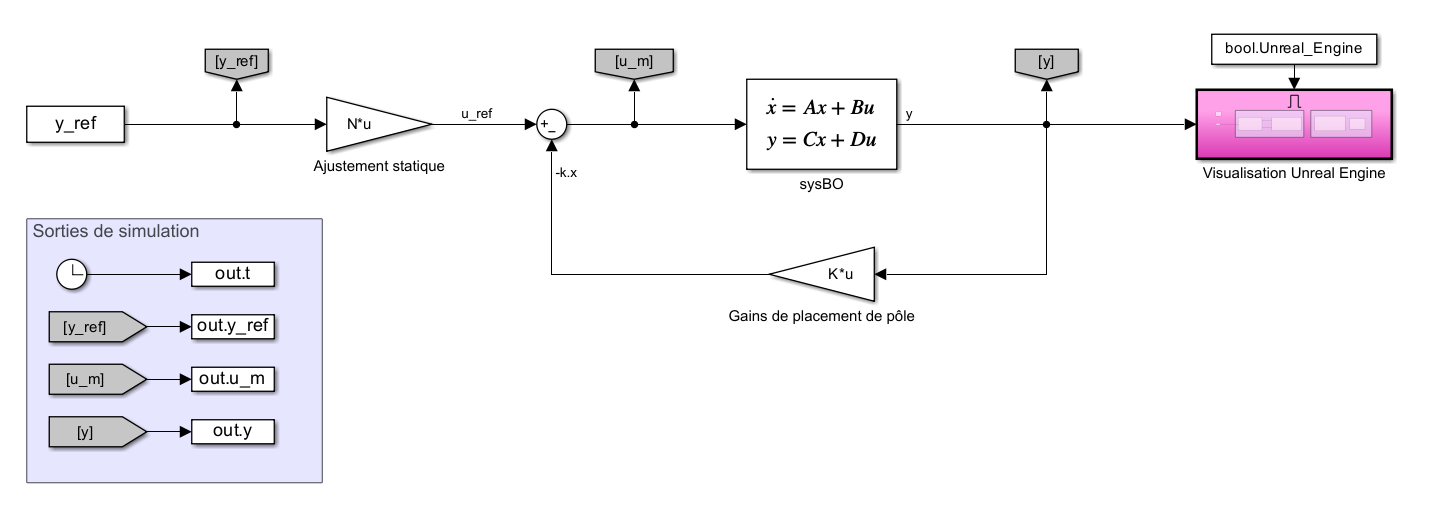

**Construisez la simulation en Boucle fermée suivante : **

- Un état initial $x_{\textrm{init}}$ défini par le groupe comme point de départ stable sur la map Unreal Engine : [Documentation Map](https://fr.mathworks.com/help/vdynblks/ref/uscityblock.html)

- Une "pose" de reference à atteindre $y_{\textrm{ref}}$ avec une consigne différente de l'état initial sur toutes ses composantes.

- Le trajet de $x_{\textrm{init}}$ vers $y_{\textrm{ref}}$ devra être séparé d'au moins 20 mètres et ne rencontrera aucun obstacles en chemin.

Presentation des résultats :

- On utilisera convenablement la fonction `animation_result_drone().`

- On construira une fonction d'affichage des résultats (partie annexe), que vous jugerez pertinent (une seule figure, avec subplots).

**Etat initial et ****consigne**** de réference :**

StopTime = 10;
t = 0 : dt_realtime : StopTime;

% état de départ
x_init=[0 ; 0 ; 0 ; 0 ; 0 ; 0 ; 0 ;0;0;0;0;0];


% état d'arrivée désiré 
y_ref_position = [15, 15, 10];      % sqrt(15^2 + 15^2 + 10^2) > 20 mètres
y_ref_orientation = [0, 0, pi/4];   % Changement du lacet de 45 degrés

y_ref = [y_ref_position(1), y_ref_position(2), y_ref_position(3), y_ref_orientation(3)];



y_ref = timeseries(y_ref .* ones(length(t),1) , t);

**Design de contrôle **et simulation :

sim2_BF=sim("Simulink_drone_BF_final.slx");

Error due to multiple causes.

Caused by:
    Error using main_projet_drone_partie_01 (line 83)
    Error evaluating parameter 'perturbation' in 'Simulink_drone_BF_final/

**Annimation et affichage:**

Starting Animation...

Final Estimated Energy (Wh): 0.00


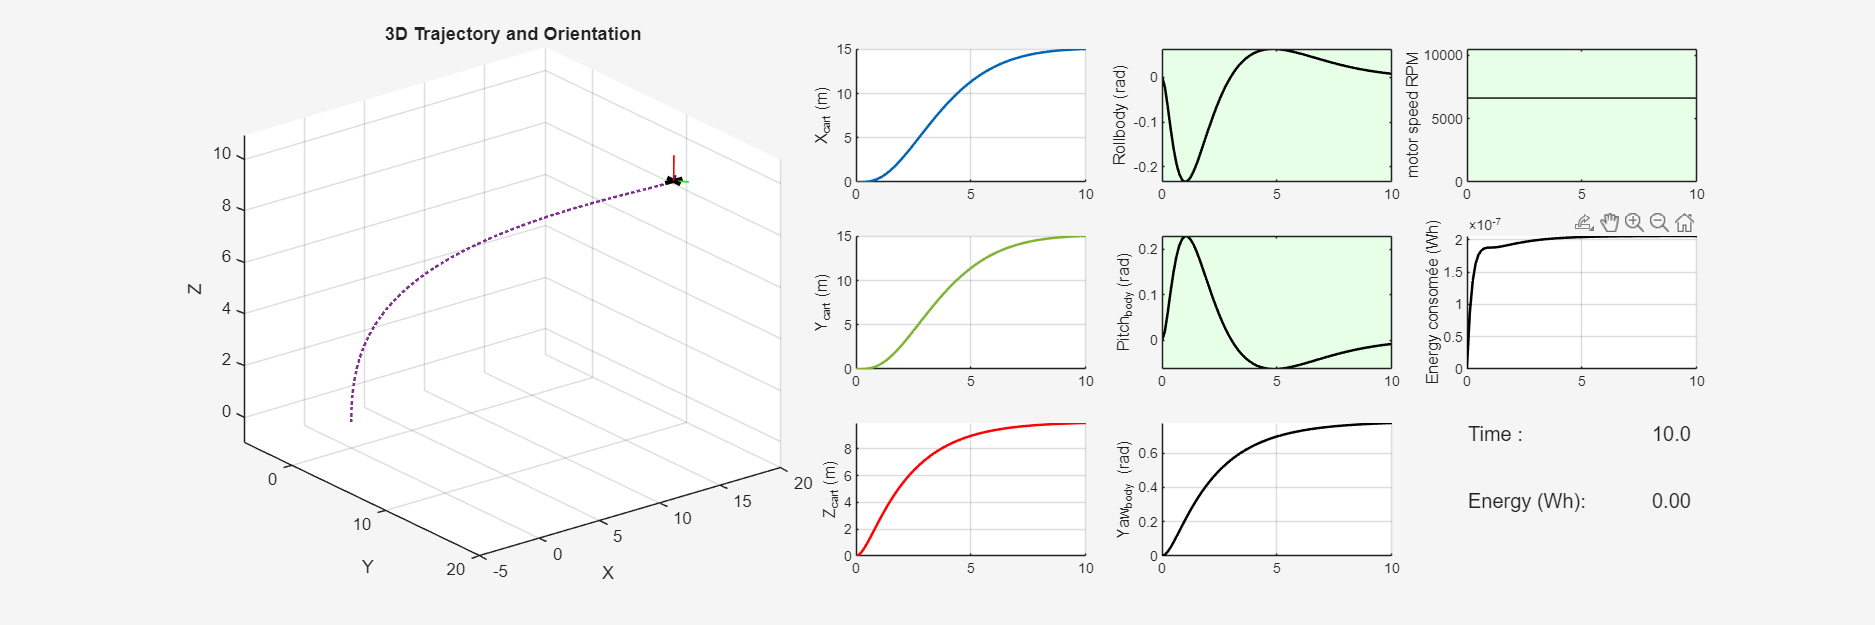

%% === Annimation et affichage ===

% 1. Configuration des options de l'animation
options = struct();
options.speed_ratio = 5;       
options.record_video = false; 

% 2. Préparation des données (Cette étape est OBLIGATOIRE pour écraser la 3D de Simulink)
% 2. Préparation des données intelligente
sim2_data = struct();
sim2_data.t.Data = sim2_BF.t.Data;

% Extraction brute (avec squeeze au cas où Simulink remet de la 3D)
u_brut = squeeze(sim2_BF.u_m.Data);
y_brut = squeeze(sim2_BF.y.Data);

% On force le tableau à se mettre dans le bon sens [Temps x Variables]
if size(u_brut, 2) ~= 4
    u_brut = u_brut'; % On transpose uniquement s'il n'y a pas 4 colonnes
end

if size(y_brut, 2) ~= 12
    y_brut = y_brut'; % On transpose uniquement s'il n'y a pas 12 colonnes
end

% On range dans la structure finale
sim2_data.u_m.Data = u_brut;
sim2_data.y.Data   = y_brut; 

% 3. Lancement de l'animation !
% ATTENTION : Il faut bien envoyer 'sim2_data' et SURTOUT PAS 'sim2_BF'
animation_result_drone(sim2_data, params, options);

**______________________________________________________________________________________**

## 6. Annexes

**Fonction d'affichage des résultats d'une simulation en boucle fermée**

*Inspiration TD 02-03*